n = 4;       % number of agents
k_max = 100; % max time steps
Lu = 5;      % maximum number of consecutive sleeping instants
Lf = 5;      % maximum number of consecutive link fails
Ldel = 5;    % maximum number of delays
wake_prob = 1.00;
loss_prob = 0.00;
blind_prop = 0.00;

## Observations

at each instant $k$ each agent samples the distance from it to the target with lower precision as the distance inscreases.


$$S_i =N\left(\mu =d,\sigma =d\right)$$


xmax = 10;
pos = rand([n,2])*xmax;
target = rand([1,2])*xmax;
%target = [0.5 0.5]*xmax;
disp(target)

    8.8223    8.8681



mu_f = zeros(n,1);
sigma_f = zeros(n,1);
S = zeros(n,k_max);
for i = 1:n
    distance = norm(pos(i,:)-target);
    mu_f(i) = distance;
    % sigma_f(i) = distance;
    sigma_f(i) = 1;
    S(i,:) = randn(1,k_max)*sigma_f(i)+mu_f(i);
end

## Hypothesis

The space is discretized considering a grid with uniformly spaciated cells where each cell will have its corressponding hypothesis (the parameters of the hypothesis are the expected $\mu \;$ and $\sigma \;$that would be seen if he hypothesis were true).

**Note: in this case using **$\sigma =1$ **leads to approrpiate results. However, using **$\sigma =d$ **as would be correct leads to wrong results since very wide distributions appear to have lower KLD than the real ones.**

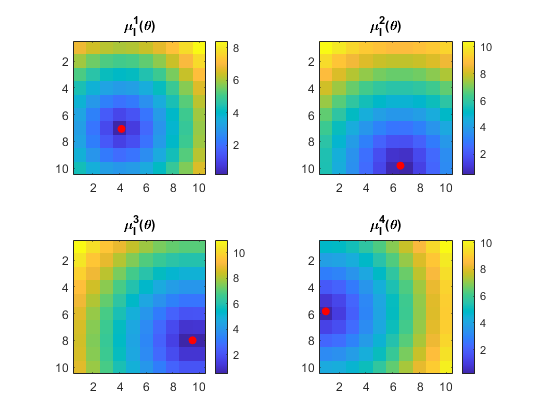

steps = 10;
m = steps^2;
sigma_l = zeros(n,m);
mu_l = zeros(n,m);
for i = 1:n
    sigma_l(i,:) = sigma_f(i);
    mu_l(i,:) = mu_f(i);
    if(rand()>blind_prop)
        for x = 1:steps
            for y = 1:steps
                ind = steps*(x-1)+y;
                x_m = x*xmax/steps;
                y_m = y*xmax/steps;
                distance = norm(pos(i,:)-[x_m y_m]);
                mu_l(i,ind) = distance;
                sigma_l(i,ind) = distance;
                % sigma_l(i,ind) = 1;
            end
        end
    end
end
figure(1)
clf
xc = linspace(1,xmax,steps);
yc = linspace(1,xmax,steps);
k = 1;
for i = 1:floor(sqrt(n))
    for j = 1:floor(sqrt(n))
        subplot(floor(sqrt(n)),floor(sqrt(n)),k)
        mat = list2mat(mu_l(k,:),steps);
        image(xc, yc, mat,"CDataMapping","scaled")
        title(['\mu_l^' num2str(k) '(\theta)'])
        colorbar
        hold on
        scatter(pos(k,2),pos(k,1),'r','filled')
        k = k+1;
    end
end

## Cost Function

The cost function compares the original distribution with the hypothesis and adds up the results of each agent in order to find the global optimum. A single agent would be unable to determine the real position but 2 or more can. 

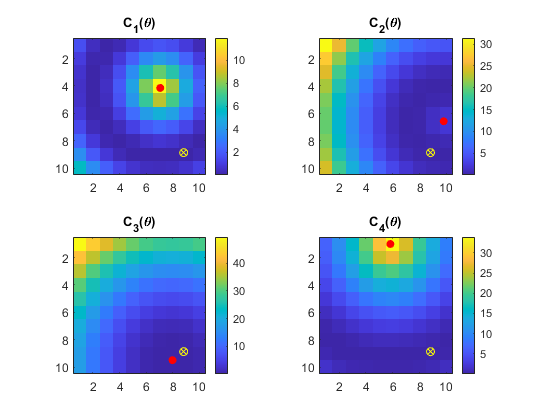

C_ind = zeros(steps,steps,n);
C_table = zeros(steps,steps);
C_ast = inf;
x_ast = xmax/2;
y_ast = xmax/2;
for i = 1:steps
    for j = 1:steps
        x_m = i*xmax/steps;
        y_m = j*xmax/steps;
        for k = 1:n
            distance = norm(pos(k,:)-[x_m y_m]);
            mu_m = distance;
            % sigma_m = distance;
            sigma_m = 1;
            C_table(i,j) = C_table(i,j) + KLDivNorm(sigma_f(k),mu_f(k),sigma_m,mu_m);
            C_ind(i,j,k) = KLDivNorm(sigma_f(k),mu_f(k),sigma_m,mu_m);
        end
        if(C_table(i,j)<C_ast)
            C_ast = C_table(i,j);
            x_ast = x_m;
            y_ast = y_m;
            theta_ast = (y_ast-1)*steps+x_ast;
            %disp(['optimo actualizado, pos = [' num2str(x_ast) ',' num2str(y_ast) '], C = ' num2str(C_ast)])
        end
    end
end
figure(2)
clf
k = 1;
for i = 1:floor(sqrt(n))
    for j = 1:floor(sqrt(n))
        subplot(floor(sqrt(n)),floor(sqrt(n)),k)
        image(xc, yc, C_ind(:,:,k)',"CDataMapping","scaled")
        title(['C_' num2str(k) '(\theta)'])
        %image(xc, yc, max(-n,C_table),"CDataMapping","scaled")
        colorbar
        hold on
        scatter(target(1),target(2),'yx')
        scatter(target(1),target(2),'yo')
        scatter(pos(k,1),pos(k,2),'r','filled')
        k = k+1;
    end
end

disp(['the optimal solution is (' num2str(x_ast) ', ' num2str(y_ast) ') with a cost value of ' num2str(C_ast)])

the optimal solution is (9, 9) with a cost value of 0.040438


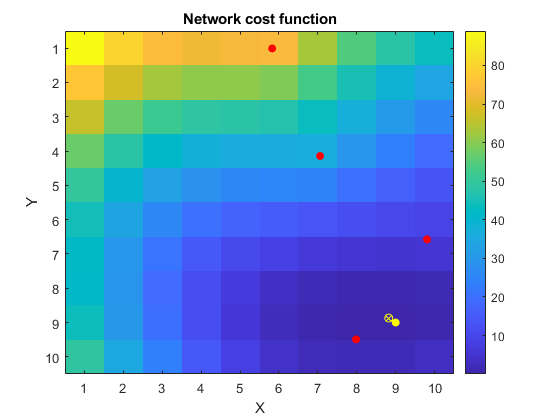

figure(2)
clf
image(xc, yc, C_table',"CDataMapping","scaled")
xlabel('X')
ylabel('Y')
title('Network cost function')
%image(xc, yc, max(-n,C_table),"CDataMapping","scaled")
colorbar
hold on
scatter(x_ast,y_ast,'y','filled')
scatter(target(1),target(2),'yx')
scatter(target(1),target(2),'yo')
scatter(pos(:,1),pos(:,2),'r','filled')

## Network

The agents interact through a faulty star network.

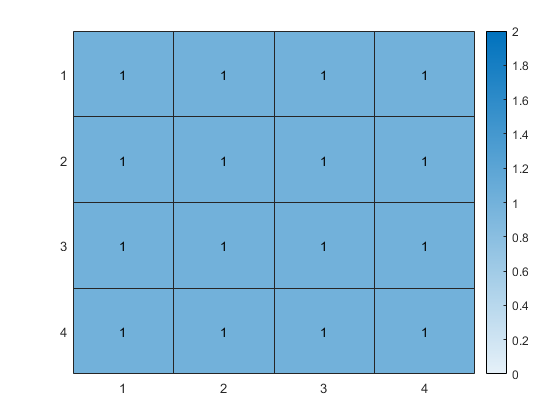

G = ones(n,n,k_max);
% G = zeros(n,n,k_max);
% for i = 1:n
%     for k = 1:k_max
%         G(i,i,k) = 1;
%         G(i,1,k) = 1;
%         G(1,i,k) = 1;
%     end
% end
figure(3)
clf
heatmap(G(:,:,1))

## Algorithm

wake_counter = zeros(n,1);
loss_counter = zeros(n,1);
% agents initialization
clear V
for i = 1:n
    V(i) = Agent3(i, n, m, mu_l(i,:), sigma_l(i,:), sum(G(:,i,1))-1, Ldel); %#ok<SAGROW>
end
% visualization variables
mu_v = ones(n,m,k_max+1)/m;
y_v = zeros(n,k_max+1);
od_v = zeros(n,k_max+1);
k_v = zeros(n,n,k_max+1);
phi_y_v = zeros(n,k_max+1);
rho_y_v = zeros(n,n,k_max+1);
rhos_y_v = zeros(n,n,k_max+1);
phi_mu_v = zeros(n,m,k_max+1);
G_v = G;
wake_v = zeros(n,k_max+1);
C = zeros(k_max+1,1);
stop = false;
convergence = false;
mu_min = 0.001;
% iterative loop
for k = 1:k_max
    % actual algorithm
    for i = 1:n
        V(i) = V(i).idleBehavior();
        if (rand < wake_prob || wake_counter(i) >= Lu)
            wake_counter(i) = 0;
            wake_v(i,k+1) = 1;
            od = sum(G(:,i,k))-1; % output degree
            V(i) = V(i).selfUpdate(k, S(i,k), od);
            for j = 1:n % messages broadcast
                if(G(i,j,k) == 1)
                    if(rand > loss_prob || loss_counter(i) >= Lf)
                        delay = randi([0,Ldel]);
                        V(j) = V(j).receiveMessage(V(i).ID, V(i).phi_y, V(i).phi_mu, k, delay);
                        loss_counter(i) = 0;
                    else
                        loss_counter(i) = loss_counter(i) + 1;
                        G_v(i,j,k) = 0;
                    end
                end
            end
            % Beliefs Updating
            if(sum(isnan(V(i).mu))~=0)  % Check for NaN hypothesis
                disp(['NaN detectado en el agente ' num2str(i) ' en la iteración ' num2str(k)])
                stop = true;
                break
            end
            V(i) = V(i).processMessages();
        else
            wake_counter(i) = wake_counter(i) + 1;
            G_v(i,:,k) = zeros(1,n);
        end
        for j = 1:n
            rhos_y_v(i,j,k+1) = V(i).y_buff(j);
        end
    end
    for i =1:n
        [value, theta_c] = max(V(i).mu);
        if(theta_c~=theta_ast || value <0.99)
            convergence = false;
            break
        end
        convergence  = true;
    end
    % visualization
    for i = 1:n
        for p = 1:m
            mu_v(i,p,k+1) = V(i).mu(p);
        end
        y_v(i,k+1) = V(i).y;
        od_v(i,k+1) = V(i).od;
        for j = 1:n
            k_v(i,j,k+1) = V(i).ki(j);
        end
        phi_y_v(i,k+1) = V(i).phi_y;
        for p = 1:m
            phi_mu_v(i,p,k+1) = V(i).phi_mu(p);
        end
        for j = 1:n
            rho_y_v(i,j,k+1) = V(i).rho_y(j);
        end
        [~, a_theta] = max(V(i).mu(:));
        C(k+1) = C(k+1) - KLDivNorm(sigma_f(i),mu_f(i),sigma_l(i,a_theta),mu_l(i,a_theta));
    end
    % Stop condition
    if(stop || convergence)
        mu_v = mu_v(:,:,1:k+1);
        y_v = y_v(:,1:k+1);
        od_v = od_v(:,1:k+1);
        k_v = k_v(:,:,1:k+1);
        phi_y_v = phi_y_v(:,1:k+1);
        phi_mu_v = phi_mu_v(:,:,1:k+1);
        rho_y_v = rho_y_v(:,:,1:k+1);
        rhos_y_v = rhos_y_v(:,:,1:k+1);
        wake_v = wake_v(:,1:k+1);
        C = C(2:k+1);
        G = G(:,:,1:k);
        G_v = G_v(:,:,1:k+1);
        if(stop)
            disp(['Falló por detección de NaN tras ' num2str(k) ' iteraciones'])
        else
            disp(['Todos los agentes convergieron en ' num2str(k) ' iteraciones'])
        end
        break
    end
end

## Interest Plots

### Cost function

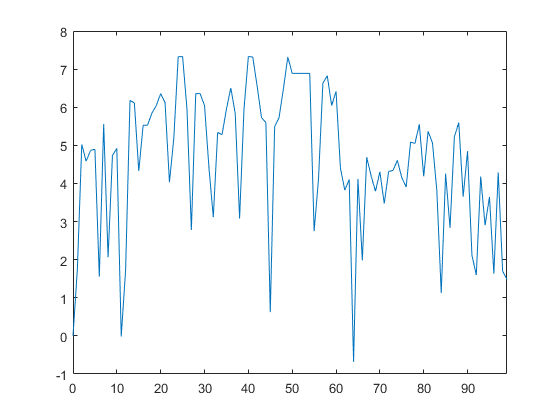

figure(4)
plot(0:length(C)-1,C)
xlim([0,k-1])

### Average Beliefs

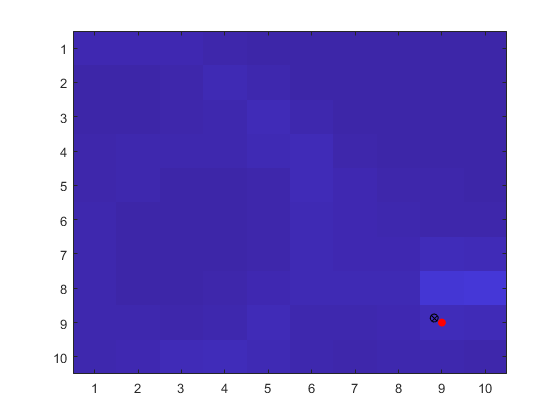

figure(5)
for t = 1:k+1
    mu_p = reshape(sum(mu_v(:,:,t),1)/n,steps,steps);
    image(xc, yc, mu_p',"CDataMapping","scaled")
    ax = gca;
    ax.CLim = [0,1];
    hold on
    scatter(x_ast,y_ast,'r','filled')
    scatter(target(1),target(2),'kx')
    scatter(target(1),target(2),'ko')
    %colorbar
    hold off
    pause(0.1)
end

### Individual Beliefs

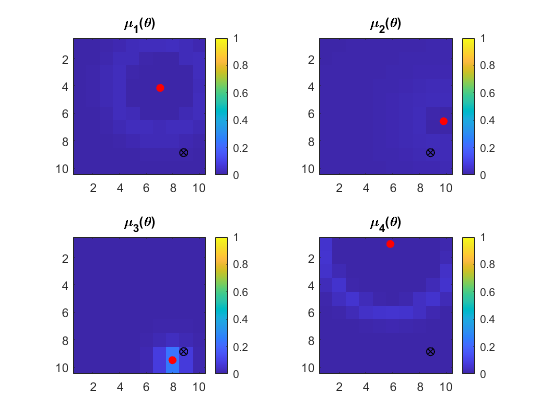

figure(6);
for t = 1:k+1
    a = 1;
    for i = 1:floor(sqrt(n))
        for j = 1:floor(sqrt(n))
            mu_p = list2mat(mu_v(a,:,t),steps);
            subplot(floor(sqrt(n)),floor(sqrt(n)),a)
            image(xc, yc, mu_p',"CDataMapping","scaled")
            ax = gca;
            ax.CLim = [0,1];
            title(['\mu_' num2str(a) '(\theta)'])
            hold on
            scatter(target(1),target(2),'kx')
            scatter(target(1),target(2),'ko')
            scatter(pos(a,1),pos(a,2),'r','filled')
            colorbar
            hold off
            a = a+1;
        end
    end
    pause(0.1)
end

### Awaken

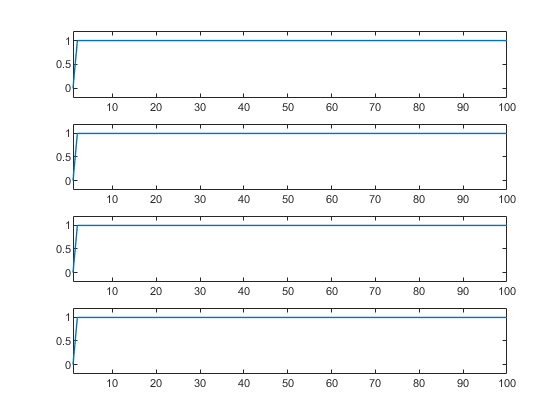

f7 = figure(7);
clf
set(f7, 'Position', [0 0 1000 200*min(n,10)])
for i = 1:min(n,10)
    subplot(min(n,10),1,i)
    plot(wake_v(i,:),'LineWidth',1)
    xlim([1,k])
    ylim([-0.2,1.2])
end

### Self Weight $y_i \left\lbrack k\right\rbrack$

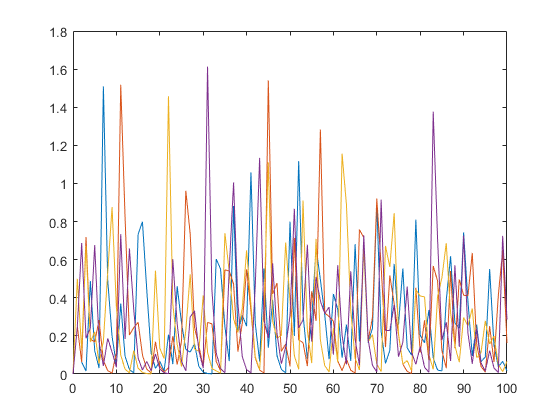

figure(8);
clf
plot(0:k,y_v)

### Weights Average $\bar{y_i } \left\lbrack k\right\rbrack$

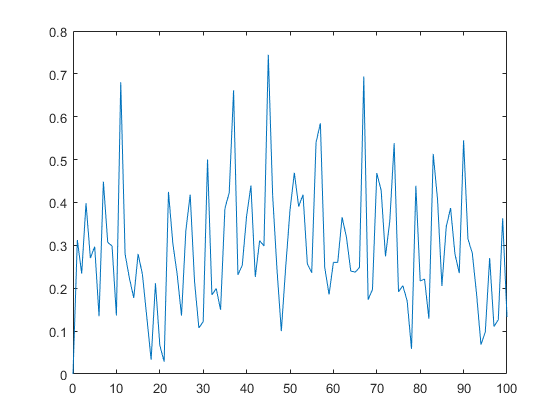

figure(9);
clf
plot(0:k,sum(y_v,1)/n)

### Weight Sent at each k $\phi_i^y \left\lbrack k\right\rbrack -\phi_i^y \left\lbrack k-1\right\rbrack$

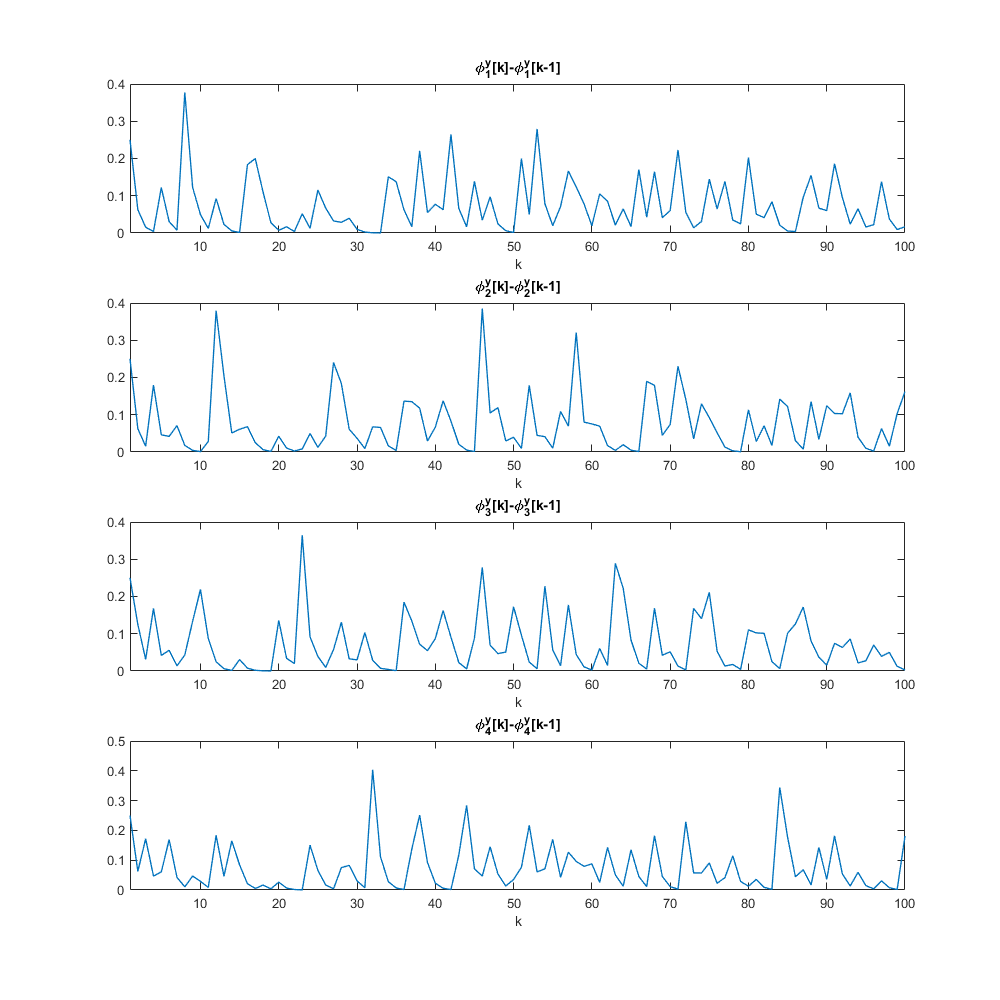

f10 = figure(10);
clf
set(f10, 'Position', [0 0 1000 250*min(n,10)])
phi_plot = diff(phi_y_v,1,2);
for i = 1:min(n,10)
    subplot(min(n,10),1,i)
    plot(1:k, phi_plot(i,:),'LineWidth',1)
    xlim([1,k])
    xlabel('k')
    title(['\phi_' num2str(i) '^y[k]-\phi_' num2str(i) '^y[k-1]'])
end

## Functions 

function mat = list2mat(list, steps)
    mat = zeros(steps);
    for x = 1:steps
        for y = 1:steps
            mat(x,y) = list(steps*(x-1)+y);
        end
    end
end